% 1. Parametrelerin Belirlenmesi
simParams.sampleRate = 20e6;    % Örnekleme frekansı (20 MHz)
N_samples = 400;                % Test edilecek örnek sayısı
fs = simParams.sampleRate;
t = (0:N_samples-1).' / fs;

% 2. Temiz Sinyal Üretimi (Örn: Basit bir QPSK sembol dizisi veya Karmaşık Sinüs)
% Anlaşılır olması için 1 MHz'lik temiz bir referans sinyali oluşturuyoruz.
% Üzerine gerçekçi olması için biraz da AWGN (gürültü) ekliyoruz.
temiz_sinyal = complex(cos(2*pi*1e6*t), sin(2*pi*1e6*t));
temiz_sinyal = temiz_sinyal + complex(randn(N_samples,1)*0.05, randn(N_samples,1)*0.05);

% 3. Sinyali Havada Bozalım (Frekans Sapması Ekleyelim)
% Havada 125,500 Hz'lik bir frekans kaymasına uğradığını varsayalım
foffset_gercek = 125500; 
bozuk_sinyal = temiz_sinyal .* exp(1i * 2 * pi * foffset_gercek * t);

% Önceki algoritmanın bu sapmayı 125,481 Hz olarak tahmin ettiğini varsayalım
tahmin_edilen_cfo = 125481; 

% 4. Fonksiyonları Çağırma (Düzeltme İşlemi)
% Floating-Point (Referans) Düzeltme
y_fl = coarseCFOcorrection(bozuk_sinyal, tahmin_edilen_cfo, simParams);

% Fixed-Point (Donanım Modeli) Düzeltme
y_fix = coarseCFOcorrection_fixed(bozuk_sinyal, tahmin_edilen_cfo, simParams);

% 5. Hata Analizi ve Konsol Çıktısı
hata_vektoru = y_fl - double(y_fix);
rms_hata = sqrt(mean(abs(hata_vektoru).^2));
rms_ref = sqrt(mean(abs(y_fl).^2));
evm_yuzde = (rms_hata / rms_ref) * 100; % Error Vector Magnitude

fprintf('===================================================\n');

fprintf('--- CFO Düzeltme (Digital Mixer) Sonuçları ---\n');

--- CFO Düzeltme (Digital Mixer) Sonuçları ---


fprintf('===================================================\n');

fprintf('Sinyale Eklenen Gerçek CFO : %10.2f Hz\n', foffset_gercek);

Sinyale Eklenen Gerçek CFO :  125500.00 Hz


fprintf('Düzeltme İçin Kullanılan   : %10.2f Hz\n', tahmin_edilen_cfo);

Düzeltme İçin Kullanılan   :  125481.00 Hz


fprintf('---------------------------------------------------\n');

---------------------------------------------------


fprintf('RMS Kuantizasyon Hatası    : %e\n', rms_hata);

RMS Kuantizasyon Hatası    : 2.778623e-02


fprintf('EVM (Hata Vektör Genliği)  : %% %.4f\n', evm_yuzde);

EVM (Hata Vektör Genliği)  : % 2.7611


fprintf('===================================================\n');

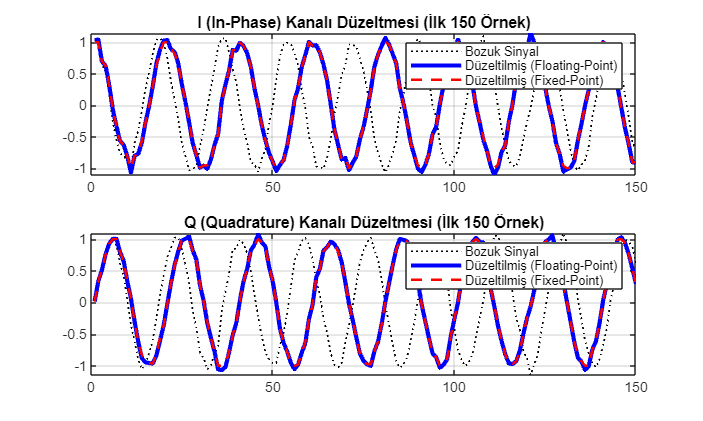


% 6. Görselleştirme
figure('Name', 'CFO Düzeltme Karşılaştırması', 'Position', [100, 100, 1000, 600]);

subplot(2,1,1);
plot(real(bozuk_sinyal(1:150)), 'k:', 'LineWidth', 1); hold on;
plot(real(y_fl(1:150)), 'b', 'LineWidth', 2.5);
plot(real(double(y_fix(1:150))), 'r--', 'LineWidth', 1.5);
title('I (In-Phase) Kanalı Düzeltmesi (İlk 150 Örnek)');
legend('Bozuk Sinyal', 'Düzeltilmiş (Floating-Point)', 'Düzeltilmiş (Fixed-Point)');
grid on;

subplot(2,1,2);
plot(imag(bozuk_sinyal(1:150)), 'k:', 'LineWidth', 1); hold on;
plot(imag(y_fl(1:150)), 'b', 'LineWidth', 2.5);
plot(imag(double(y_fix(1:150))), 'r--', 'LineWidth', 1.5);
title('Q (Quadrature) Kanalı Düzeltmesi (İlk 150 Örnek)');
legend('Bozuk Sinyal', 'Düzeltilmiş (Floating-Point)', 'Düzeltilmiş (Fixed-Point)');
grid on;



%% ========================================================================
% 1. FLOATING-POINT FONKSİYONLAR (Orijinal Kod)
% =========================================================================

function y = coarseCFOcorrection(u, foffset, simParams)
    y = localFrequencyOffset(u, simParams.sampleRate, -foffset);
end

function y = localFrequencyOffset(x, sampleRate, offset)
    narginchk(3,3);
    validateattributes(x, {'double','single'}, {'2d','nonnan','finite'}, 'frequencyOffset', 'X');
    validateattributes(sampleRate, {'double','single'}, {'scalar','real','nonnan','finite','>',0}, 'frequencyOffset', 'SampleRate');
    validateattributes(offset, {'double','single'}, {'row','real','nonnan','finite'}, 'frequencyOffset', 'OFFSET');
    
    if ~isscalar(offset) && (size(x,2) ~= size(offset,2))
        error('FrequencyOffset:DimensionMismatch', 'Offset vektörünün sütun sayısı X ile aynı olmalıdır.');
    end
    
    fs = cast(sampleRate, 'like', x);
    freqOffset = cast(offset, 'like', x);
    piVal = cast(pi, 'like', x);
    
    t = ((0:size(x,1)-1) ./ fs).';
    y = x .* exp(1i * 2 * piVal * freqOffset .* t);
end

%% ========================================================================
% 2. FIXED-POINT FONKSİYONLAR (Donanım Modeli)
% =========================================================================

function y_fi = coarseCFOcorrection_fixed(u, foffset, simParams)
    % 1. Fixed-Point Yapılandırması (16-bit veri yolu)
    T_rx = numerictype(1, 16, 15); 
    F_sat = fimath('RoundingMethod', 'Floor', 'OverflowAction', 'Saturate');

    u_fi = fi(u, T_rx, F_sat);
    N = size(u_fi, 1);
    fs = simParams.sampleRate;

    % 2. Phase Accumulator (Faz Toplayıcı) Adımı
    % Her bir örnek için eklenecek faz miktarı (Radyan)
    delta_theta = 2 * pi * (-foffset) / fs;

    % Zaman indeksini donanımdaki sayıcı (counter) gibi düşünün
    t_indices = (0:N-1).';
    theta_vec = delta_theta .* t_indices;

    % Fazı [-pi, pi] aralığına sar (Donanımdaki overflow/taşma mantığı)
    theta_vec = mod(theta_vec + pi, 2*pi) - pi;

    % 3. NCO (Numerically Controlled Oscillator) / LUT Simülasyonu
    % Cos ve Sin değerlerini donanımdaki LUT gibi 16-bit olarak sınırlandırıyoruz.
    T_nco = numerictype(1, 16, 15); 
    nco_cos = fi(cos(theta_vec), T_nco, F_sat);
    nco_sin = fi(sin(theta_vec), T_nco, F_sat);

    % 4. Complex Mixer (Dijital Mikser: 4 Çarpıcı, 2 Toplayıcı)
    u_real = real(u_fi);
    u_imag = imag(u_fi);

    % I_out = I_in * cos - Q_in * sin
    % Çarpım sonuçlarını anında 16-bit'e cast ederek veri yolunu sabit tutuyoruz.
    y_real = fi(double(u_real) .* double(nco_cos) - double(u_imag) .* double(nco_sin), T_rx, F_sat);
    
    % Q_out = I_in * sin + Q_in * cos
    y_imag = fi(double(u_real) .* double(nco_sin) + double(u_imag) .* double(nco_cos), T_rx, F_sat);

    y_fi = complex(y_real, y_imag);
end